# `第`**5**`章`  `数据和函数的可视化`

#### 5.1     `引 导`

#### 5.1.1   `离散数据的可视化`

 ` 一对``实数标量``（`**x,y**`）``可表示为平面上的一个``点``；`

`    一对``实数“向量”` ** （x，y） **`可表现为平面上的``一组点``。`

       MATLAB`就是利用这种几何比拟法实现了``离散数据``可视化。`

 `  离散数据的来源：`

    `本生离散数据：统计数据，实验数据，采样数据`

    `数值计算的离散数据：`

`        ▶``根据离散函数特征选一组自变量`x=[x1,x2,…,xN]T

`        ▶``根据所给离散函数` `算得相应的` `，`

 `   在平面上几何地表现向量对(x,y)``。`

#### 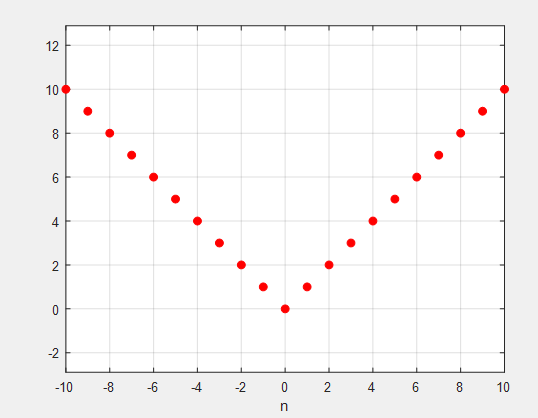

####                         `图` 5.1-1  `离散函数的可视化`

#### `【例`5.1-1`】以函数` `的图形表示离散函数。`

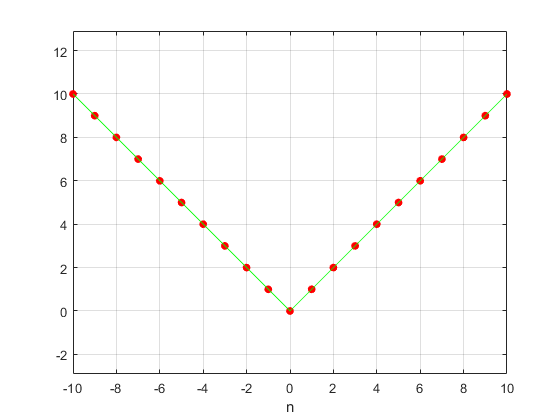

HL =   Line - 属性:

              Color: [0 1 0]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-10 -9 -8 -7 -6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7 8 9 10]
              YData: [10 9 8 7 6 5 4 3 2 1 0 1 2 3 4 5 6 7 8 9 10]
              ZData: [1×0 double]

  显示 所有属性


n=(-10:10)';  %产生一组间距为1（默认）的自变量数据
y=abs(n);     %数组算法计算相应点的函数值
HP=plot(n,y,'r.','MarkerSize',20);   %
axis equal    %为恰当显示和横、纵坐标的夹角
grid on        
xlabel('n')        
 
hold on
HL=plot(n,y,'-g')    % LineWidth:5

#### 5.1.2   `连续函数的可视化`

`    连续函数可视化包含``三个``重要环节：`

`  1. 选定一组自变量采样点（包括采样的起点、终点和采样步长）`

`    由所给函数计算相应的函数离散数据；`

    2.  `离散数据的可视化；`

    3.  `图形上离散点的连续化，方法有两种`

`    ▶``增加离散点数量获得“连续感”，计算量很大，实际中很少采用`

`    ▶``线性插值法，实质是顺次连接各离散点，计算量小，曲线连续感好`

           MATLAB`在绘制连续曲线时，根据离散采样点自动插值计算完成`

`    ▶``无论哪种方法，``自变量采样点必须``足够多``，且``单调``排列`

#### `【``例`5.1-2`】用图形表示连续调制波形` `。`

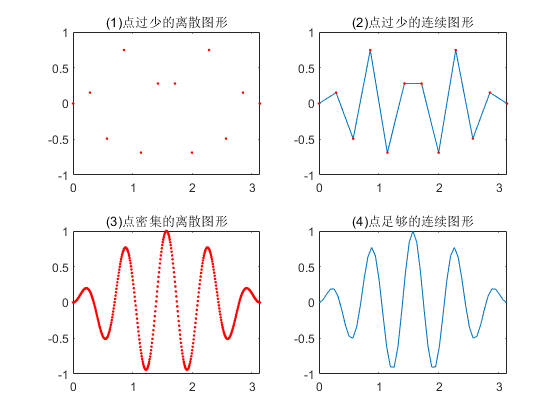

t1=(0:11)/11*pi;                % 12个采样点
t2=(0:400)/400*pi;           % 401个采样点
t3=(0:50)/50*pi;                % 51个采样点
y1=sin(t1).*sin(9*t1);          
y2=sin(t2).*sin(9*t2);
y3=sin(t3).*sin(9*t3);
subplot(2,2,1),plot(t1,y1,'r.')   % 离散点图，点太少
axis([0,pi,-1,1]),title('(1)点过少的离散图形')   
subplot(2,2,2),plot(t1,y1,t1,y1,'r.')%连续图和离散点图，点太少
axis([0,pi,-1,1]),title('(2)点过少的连续图形')
subplot(2,2,3),plot(t2,y2,'r.')   %离散点图，点密集运算量大
axis([0,pi,-1,1]),title('(3)点密集的离散图形')
subplot(2,2,4),plot(t3,y3)       % 连续图，点适中 
axis([0,pi,-1,1]),title('(4)点足够的连续图形')  

####   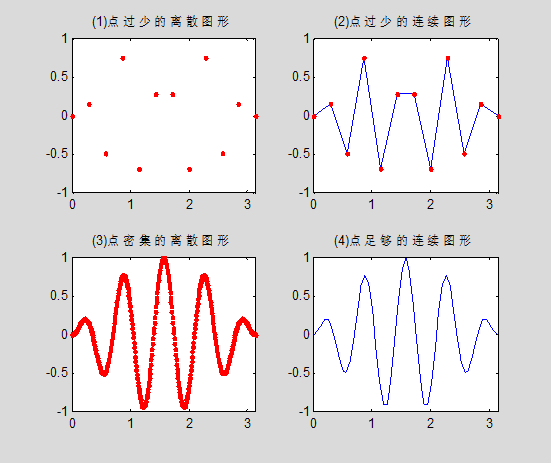

#### `                连续函数的图形表现方法`

#### `【例`5.1-3`】绘制奇数正多边形。`

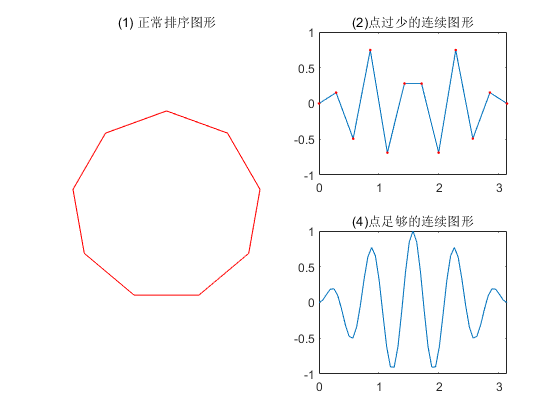

N=9;                        % 多边形的边数
t=0:2*pi/N:2*pi;             
x=sin(t);y=cos(t);           % 参数方程
tt=reshape(t,2,(N+1)/2);  
tt=flipud(tt);            % 上下两行互换
tt=tt(:);        
xx=sin(tt);yy=cos(tt);         
subplot(1,2,1),plot(x,y,'r')    
title('(1) 正常排序图形'), axis equal off shg     

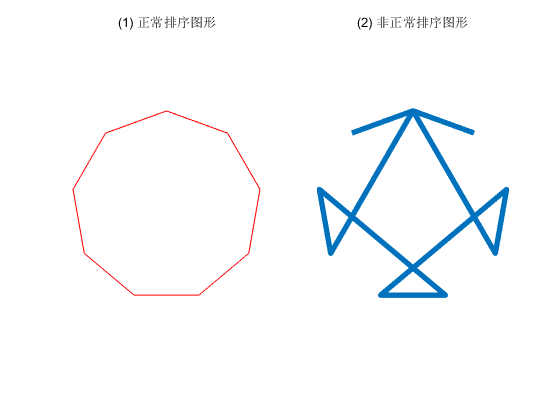

subplot(1,2,2),plot(xx,yy,'LineWidth',4)    
title('(2) 非正常排序图形'), axis equal off shg  

####  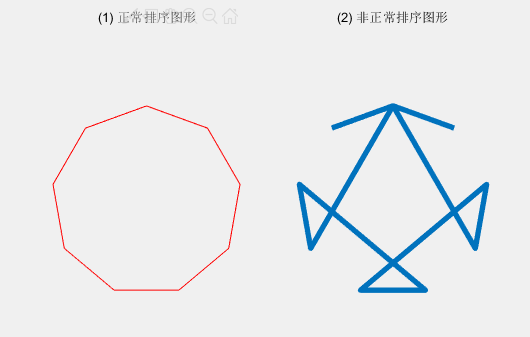

#### `       图`5.1-3  `自变量排列次序对连续曲线图形的影响`

#### 5.1.3    `图形对象分层结构和属性寻访`

**    1、**  `图形显示系统``的对象分层结构`

     图形窗口由不同的对象（如坐标轴、曲线、曲面或文字等）组成图形界面

         MATLAB`给每一个图形对象分配一个标识符，这个标识符称为``句柄``。`

`    可以把句柄``看作``指针或同类`[`对象数组`](https://baike.baidu.com/item/%E5%AF%B9%E8%B1%A1%E6%95%B0%E7%BB%84)`的`[`索引`](https://baike.baidu.com/item/%E7%B4%A2%E5%BC%95)

`    可以通过句柄对该图形对象的属性进行设置，也可以获取有关的属性，`

`    从而能够更加自主地绘制各种图形。`

     每个图形对象都拥有自己的句柄(handle)。每次创建一个对象时，

         MATLAB`就为它建立一个唯一的句柄`

#### 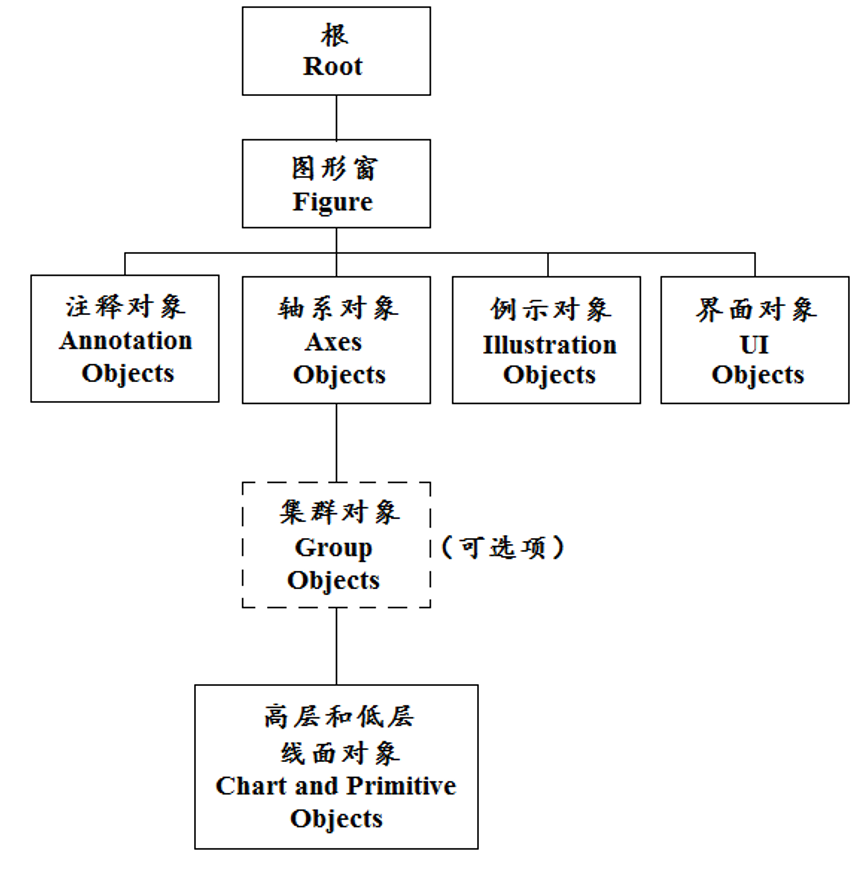

#### `2. ``图形对象属性的寻访和设置`

       class(OBN)                     `获知对象`OBN`所属的类别名`

       OBN                               `获知对象`OBN`常用属性及其取值`

       get(OBN)                        `获知对象`OBN`全部属性及当前属性值`

       set(OBN)                        `获知`OBN`全部属性及可设置属性的所有可能取值`

       OBN.pname                    `获知对象`OBN`的`pname`属性值（``点调用``）`

          OBN.pname=pvalue       `把`OBN`的`pname`属性设置为`pvalue`（点调用）`

    get(OBN,'pname')           `获知对象`OBN`的`pname`取值`

    set(OBN,'pname')           `获知对象`OBN`的`pname`属性的所有可能取值`

    set(OBN,'pname1', pvalue1,…, 'pnameN', pvalueN)    `多属性设置`

#### `〖说明〗`

    OBN表示具体图像的句柄变量名称

    pnameN `和`pvalueN`分别代表具体的属性名和属性值`

    单个对象属性的寻访和设置使用点调用格式更方便

`  一次性设置对象多个属性采用``set``指令更方便`

#### `3. ``图形窗口指令`

     `图形窗口设置指令`

        figure                                    `创建一个默认属性的图形窗口`

        figure('PropertyName',propertyvalue,...)  `创建指定属性的图形窗口`

        figure`（`H`）`       H`是已有图形句柄（句柄变量），则使其成为当前窗口`

                                 H`不存在且为整数，创建一个句柄为`H`的新图型`

    ` 图形窗口的指令：`

        clf        `清除当前图形窗图形`

        close/close(n)   `关闭当前图形窗口`/`关闭指定图形窗口`

        gcf`：`    `返回当前图形窗口的句柄；` 

        gca`：`   `返回当前图形窗口内当前坐标轴句柄；`    

        gco`：`   `返回当前窗口内图形对象中被鼠标选中的子对象的句柄`

`        如没选中子对象则返回图形句柄`

#### 5.2     `二维曲线和图形`

    MATLAB`提供了多种二维图形的绘制指令，`

`  可通过`MATLAB`帮助系统详细了解各绘图指令。最重要最基本的是`**plot**

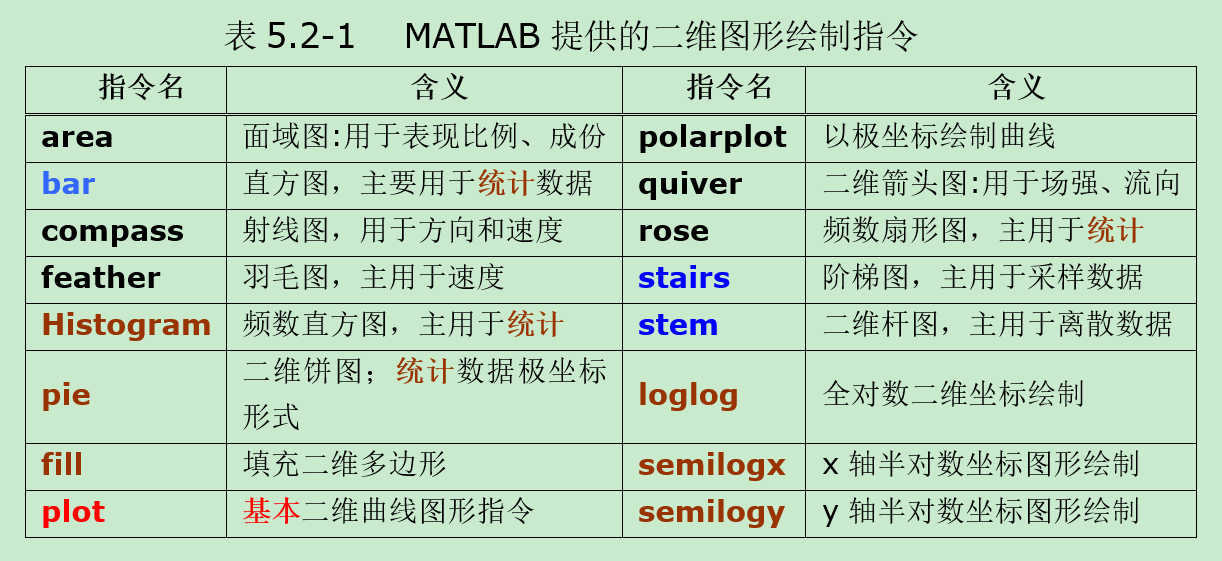

`           表`5.2-1    MATLAB`提供的二维图形绘制指令` 

#### 5.2.1     `二维曲线绘制的基本指令`**plot**

**    1.**   `基本调用格式`

    plot(*x,y*)        `用行`/`列数组绘制一条平面曲线` 

    plot(X,Y)        `用矩阵数组绘制多条平面曲线`

    plot(Y)           `用行序号作为横坐标`Y`为纵坐标绘制平面多条曲线`

#### ` 〖说明〗   `

       x,y`是长度相同的一维数组，`x`为横坐标和`y`为纵坐标`

     X,Y`是规模为〖说明〗（`m*n`）的数组，两数组对应列决定一条曲线，共`n`条`

    ▪` 绘制规则：以`X `数组的第`i `列分量作为横坐标，`

             Y`数组的第`i `列分量作为纵坐标，绘得第`i `条连线。`

        ▪ X,Y`有一个是（`m*1`）列数组时，也可绘制`n`条曲线，`

`      但`n`条曲线的横坐标（`X`为列数组）或纵坐标（`Y`为列数组）都相同`

     plot(Y) `格式：`

        Y`是一维数组：以该数组下标为横坐标，`Y`为纵坐标绘制一条曲线`

        Y`是二维数组：以该数组行下标为横坐标，`Y`为纵坐标`

`        绘制“列数”条彩色曲线，线条色彩采用默认的7种色彩次序，循环使用`

        Y`是复数：`plot(Y) `等价于`plot(real(Y),imag(Y))`，其它指令均忽略虚部`

**    2、**   **plot**`带预定义设置格式的调用格式`

`    单色或多色绘制多条曲线`

        plot(X,Y,'s')            `含预定设值符的三元组输入格式`

        plot(X1,Y1,'s1',X2,Y2,'s2', ... ,Xn,Yn,'sn')  

`        含`n`个三元组格式，每个三元组是独立的`

`    〖说明〗`

         X`，`Y `可以``均为``一维数组``，或均为`m×n`数组，``或``中有一个是``一维数组`

      `每一组三元格式`(X,Y,'s')`，只能用` ‘s’ `指定的同一颜色绘制多条曲线`

`       绘制多条曲线且`‘s’`省略，则绘制多条彩色曲线（默认的色彩次序）`

    ` 默认的点线色彩次序：由7*3``的`RGB`数组决定，取用次序由`MATLAB

`       预定义的色调数组`lines`的行序号由小到大顺序决定`

    ` 由`s`指定的线型、点形、色彩见表`

####          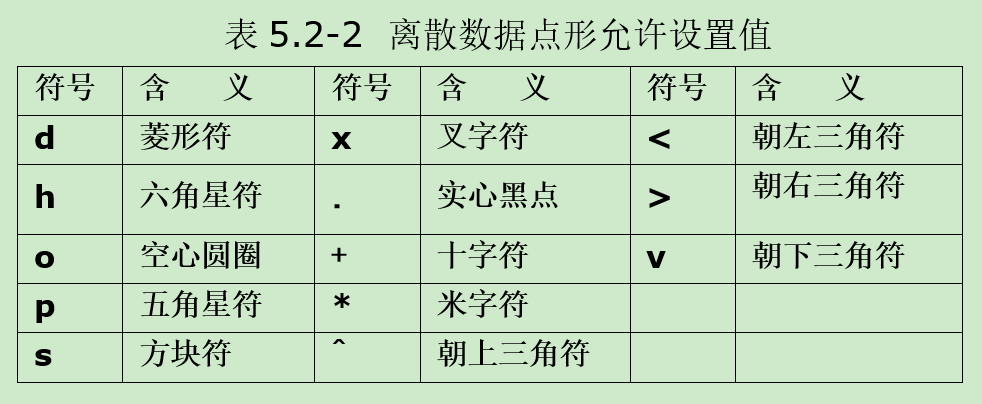

          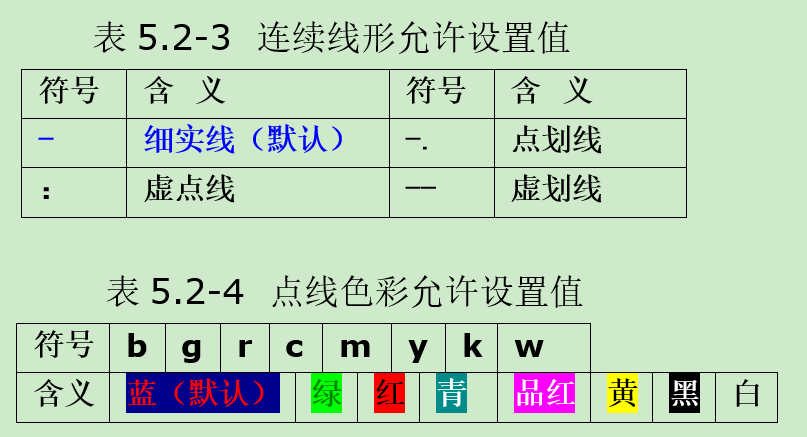

`【例`5.2-a`】二维曲线绘图指令演示之一。`plot(X,Y)`和`plot(Y)`的区别`

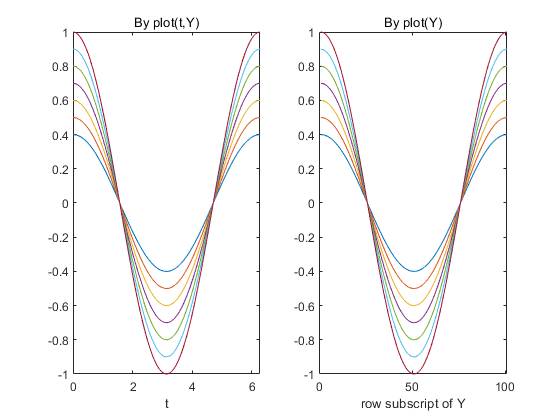

clf                            
t=(0:pi/50:2*pi)';       % (101×1)列向量
k=0.4:0.1:1;             % (1×7)行向量
Y=cos(t)*k;           % (101×7)数组

subplot(1,2,1)
plot(t,Y)               % t是一维数组，7条默认色彩曲线
title('By plot(t,Y)'),xlabel('t')

subplot(1,2,2)
plot(Y)                 %101个行坐标。指定's'变单色
title('By plot(Y)'),xlabel('row subscript of Y')  

                                               % 放大axis([0,2,0,1])

####   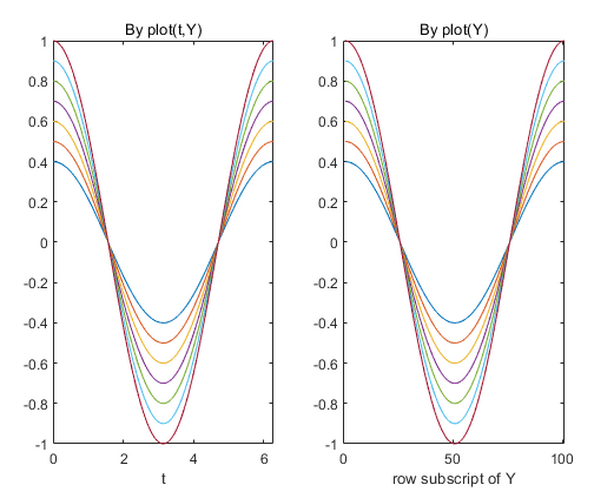

`            图` 5.2-1  plot(t,Y)`与`plot(Y)`所绘曲线的区别`

####  **3、**  `用属性名属性值精饰曲线`

`    采用属性值精饰曲线的三种方法：`

       Lh=plot(Ax,x,y,'s','PN',PV,…)     `绘图命令直接设置法`

       Lh=plot(Ax,x,y)                       

       Lh(i).PN=PV                  `点调用格式设置法，`Lh(i)`句柄的曲线对象`

       Set(Lh(i), 'PN',PV,…)    set`命令设置法`

#### `〖说明〗`

        Ax`是已存在坐标系的句柄，用于指定将图画在`Ax`指定坐标系上`

   `  省略时画在当前坐标系上`

   `  属性名` (PN) `和属性值`( PV) `用以对线的属性进行设置（表`5.2-5`）`

   `  x,y是长度相同的``列数组``绘制单条曲线`

   `  x,y``是规模相同的（``m*n``）矩阵，属性名``/``属性值影响``n``条曲线`

   `  为方便，采用‘`s`’字符串方式设置点型线型及几种常用色彩，`

`      此设置纯属为了方便，可用``属性名``/``属性值``替代`

#### 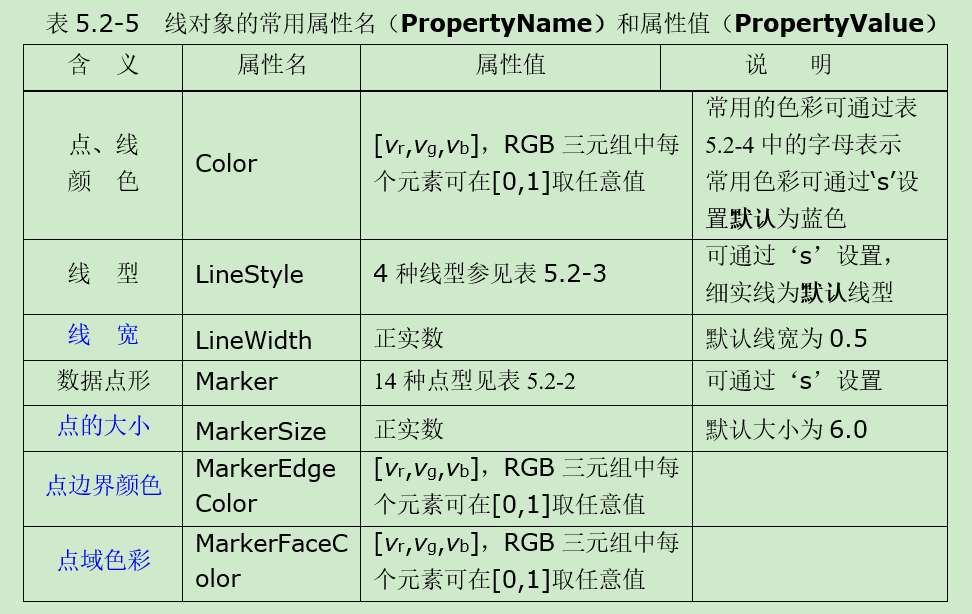

#### `【例`5.2-3`】用图形表示连续调制波形`  `及其包络线。`

figure 
t=(0:1/100:1)'*pi;              %(101,1)      <2>
yy1=sin(t)*[1,-1];              %(101,2)包络线函数值<3>
y2=sin(t).*sin(9*t);         %（101，1）调制波列向量<4>
t3=pi*(0:9)/9;               %(1,10)   过零点<5>
y3=zeros(size(t3));             
Lh1=plot(t,yy1,'--r','LineWidth',2)   %  <7>

Lh1 =   2×1 Line 数组:

  Line
  Line


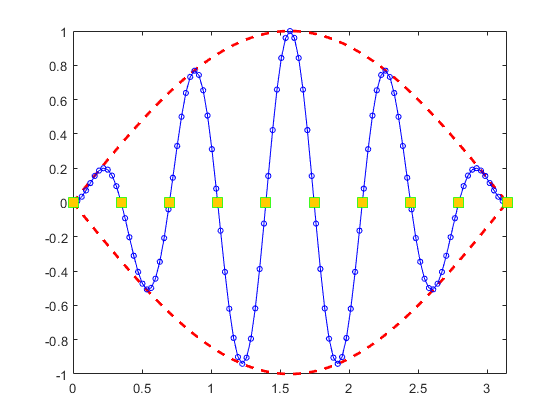

hold on                     %
Lh2=plot(t,y2,'-bo');           %  %  <9>
Lh2.MarkerSize=4;         
Lh3=plot(t3,y3,'s');         %  <11>
set(Lh3,'MarkerSize',10,'MarkerEdgeColor',[0,1,0],...  %
   'MarkerFaceColor',[1,0.8,0])               %  <13>
hold off                    %  <14>
axis([0,pi,-1,1])            %          <15>

#### 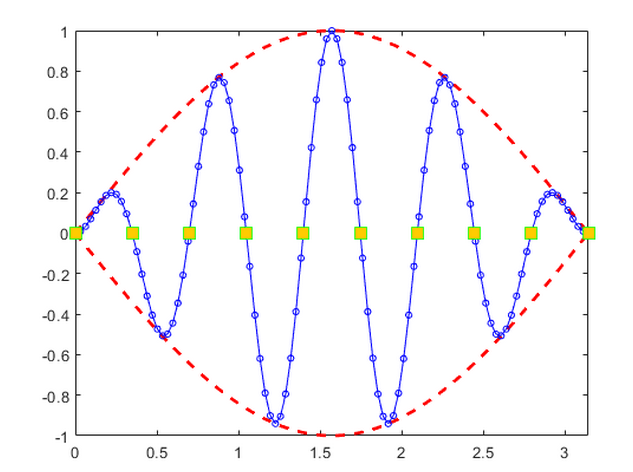               `图`5.2-2  `属性控制下所绘曲线`

#### `【例`**5.2-a**`】`

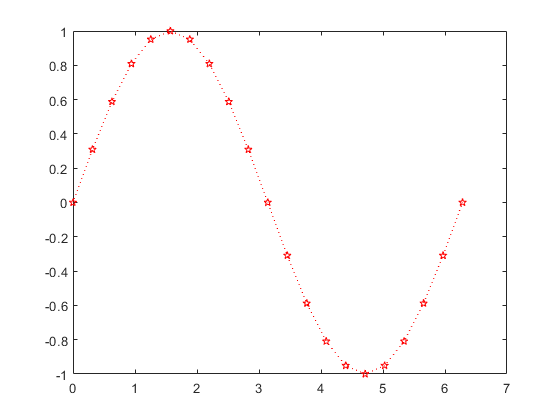

x=0:pi/10:2*pi;
h=plot(x,sin(x));   %所画图的句柄变量
set(h,'color','r','linestyle',':','marker','P');

get(h,'marker')  

ans = 'pentagram'

set(h,'color')     

  空的 0×1 cell 数组



    ans =

        'pentagram'

      空的 0×1 cell 数组

 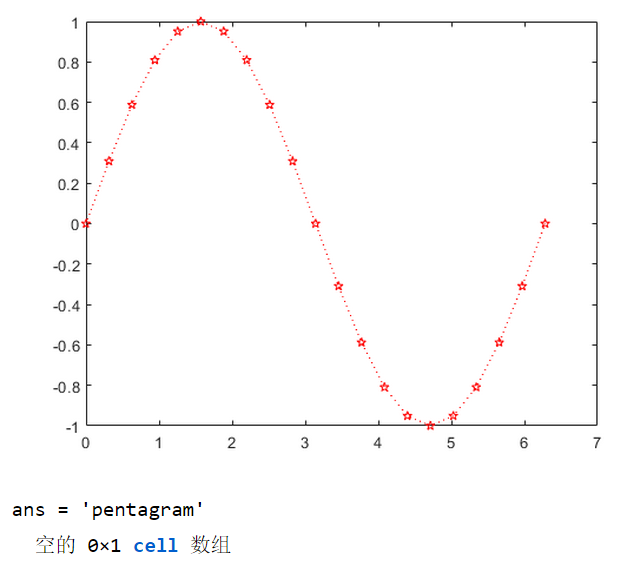    

set(h,'marker')    

  14×1 cell 数组

    {'+'        }
    {'o'        }
    {'*'        }
    {'.'        }
    {'x'        }
    {'square'   }
    {'diamond'  }
    {'v'        }
    {'^'        }
    {'>'        }
    {'<'        }
    {'pentagram'}
    {'hexagram' }
    {'none'     }



####  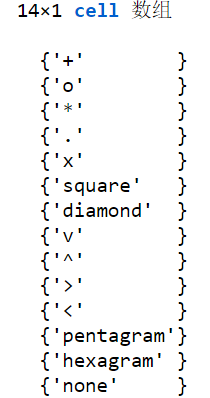

#### 5.2.2   `坐系形态和图形标识`

####    MATLAB`对图形风格的控制比较完备友善。`

####  `  在最通用的层面上，它采用了一系列考虑周全的默认设置`

#### `    无需人工干预，就能根据所给数据自动地确定坐标取向、范围、刻度、`

#### `    高宽比，给出令人满意的画面。`

####  `  在适应用户的层面上，它又给出了一系列便于使用的指令，可让用户`

#### `    根据需要和喜好改变默认设置。`

####  `  轴系对象的属性设置`

#### `    由绘图命令直接引出普适性坐标轴系，`plot, surf

#### `    借助高层命令对坐标轴系设置，`grid, Xlabel, Ylabel, title

#### `    借助轴对象句柄，用点调用格式或`set`指令设置`

#### `1、坐标轴的控制`

#### `在`MATLAB`帮助系统搜索`axis`，得到坐标轴的各种控制指令。`

#### `        表`5.2-6  `常用的坐标控制指令`

####  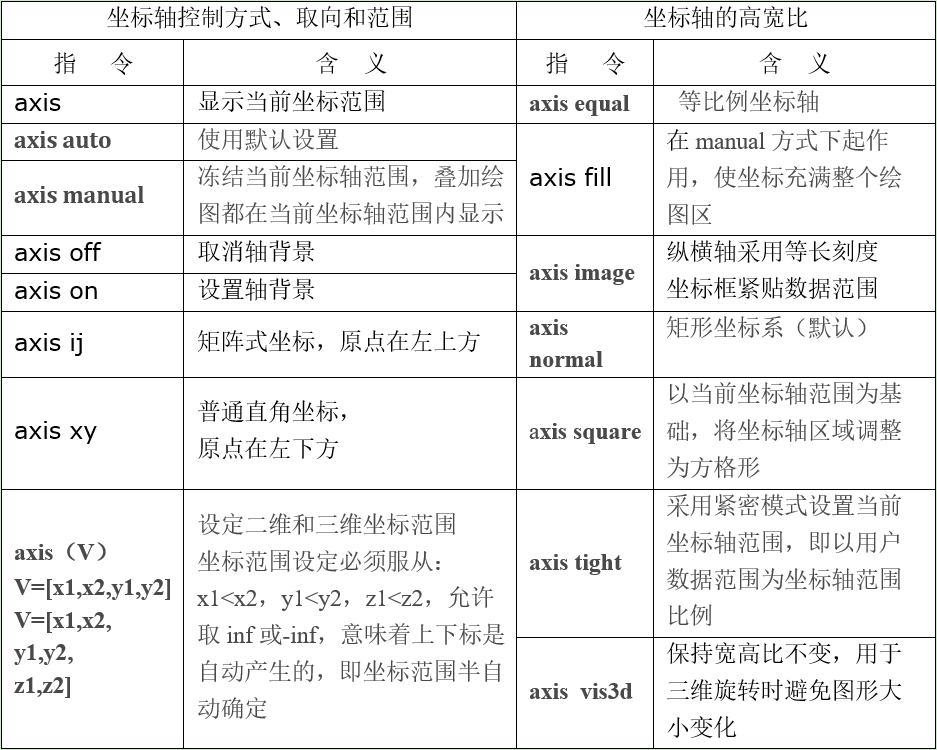

#### `【例`**5.2-4**`】``观察各种轴控制指令的影响。演示采用长轴为`3.25`，短轴为`1.15`的``椭圆``。``注意：``采用多子图表现时，图形形状不仅受“控制指令”影响，而且受整个图面“宽高比”及“子图数目”的影响。`

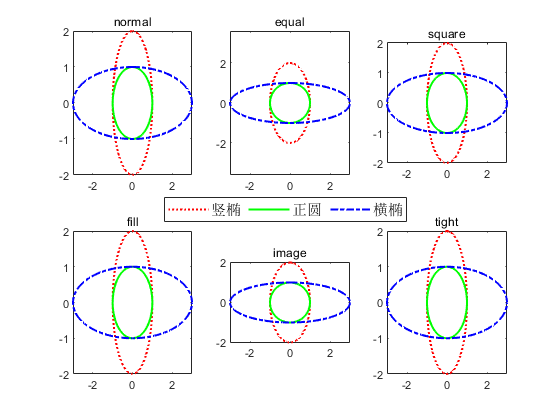

figure
t=(0:100)'*2*pi/100; % （101*1）列数组
x=sin(t)*[1,1,3];   % （101*3）数组
y=cos(t)*[2,1,1];   % （101*3）数组
S={'normal','equal','square','fill','image','tight'};
                       % 关键词字符串元胞数组
for k=1:6
   subplot(2,3,k);     %创建子图            <7>
   plot(x(:,1),y(:,1),'r:',x(:,2),y(:,2),'g-',...
      x(:,3),y(:,3),'b-.','LineWidth',1.5);
   title(S{k})      %当前轴系上注子图名
   axis(S{k})           
end
Lh=legend('竖椭','正圆','横椭','Orientation','horizontal');
    % 
Lh.FontSize=11;        %指定注释文字大小
Lh.Position=[0.374,0.472,0.272, 0.06];   %指定图例位置  <16>  

#### 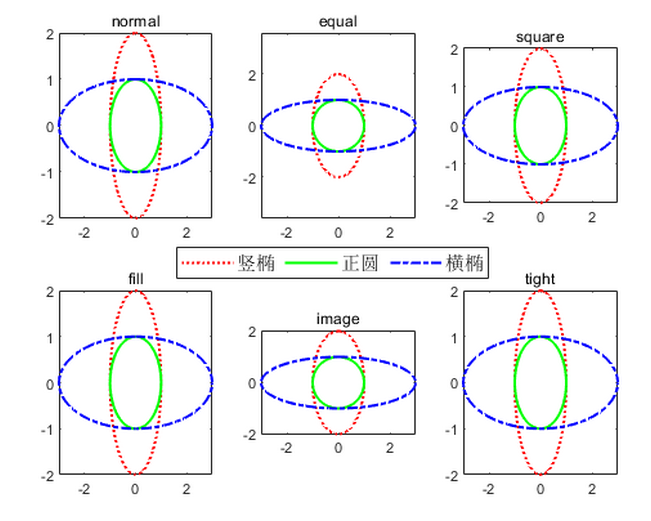 

#### `〖练习〗`

    1`、`Plot`语句中离散点符号和连续线型符号混用`

    2`、试用`plot`单独绘出各图，准确体会控制指令的影响`

#### **2**`、``坐标框、网格线、轴线分度及标识`

    box                 `坐标形式在封闭式和开启式之间切换指令`

    box on             `使当前坐标呈封闭形式（默认设置）`

    box off            `使当前坐标呈开启形式`

    grid                 `网格线的双向切换指令（使当前分格线状态翻转）`

    grid on            `在坐标刻度处画细实线网格，密度取决于坐标刻度`

    grid off       `不画分格线（默认设置）`

    grid minor   `将每个分度再`5`等分产生更细密的网格虚线，`

    xticks(XTvalue)           `设置`x`轴标尺分度位置（小竖线）`

    yticks(YTvalue)           `设置`y`轴标尺分度位置（小竖线）`

    xticklabels(XTstring)   `设置`x`轴分度值（竖线下面的数值）`

    yticklabels(YTstring)   `设置`y`轴分度值（竖线下面的数值）`

    xtickangle(XTangle)    `设置`x`轴标尺分度的`x`角度`

    ytickangle(YTangle)    `设置`y`轴标尺分度的`x`角度`

#### `〖说明〗`

     box('on')`、`grid('on')`、`axis('on')`也是合法的`

  ` 分格线的密度取决于坐标刻度，改变密度需先定义坐标刻度`

      XTvalue`和` YTvalue`为数值数组，用于指定`x`、`y`标尺分度值位置`

     XTstring`和` YTstring`为字符串元胞数组，用于`x`、`y`轴分度的标识字符`

            `元胞数组规模应与`xticks`、`yticks`指定分度位置的规模相同`

     XTangle`和` YTangle`为字标量正数，用于`x`、`y`轴分度的标识字符`

`    相对水平线的倾斜角度（用度数表示）`

   ` 以上所有指令均可将已存在的轴系句柄`Ax`用作第一输入量`

`    使命令对`Ax`轴系发挥作用，如`box(Ax,'on')

#### `3、图形标识指令`

`  图形标识：图名`(Title)`、坐标轴名`(Label)`、图形注释`(Text)`和图例`(Legend)

`  标识指令的最简捷使用格式如下：`

        title(S)                   `书写图名`

        xlabel(S)               `横坐标轴名`

        ylabel(S)            `纵坐标轴名`

        text(xt,yt,S)           `在图面`(xt, yt)`坐标处书写字符注释`

        gtext(S)                  `在图形窗口上用鼠标直接指定位置加注文本`

        legend(S1,S2, ...)    `绘制曲线所用线型、色彩或数据点形图例`

        legend(S1,S2, ...,'location',Lstring)   `显示位置由`Lstring`确定`

#### `〖说明〗`

    S`，`S1`，`S2`为字符串，`

`    可以是英文、中文或`Tex`定义的各种特殊字符（表`5.2-8`～`11`）`

    Legend`中`S1,S2, ...`分别代表所画曲线名称，顺序为画图顺序`

`    所标图例的默认位置在图形窗的右上角`

    Lstring`可以是（`1×4`）位置矢量` ([left,bottom,width,height]) `，`

`    或字符串`  'North' `、`  'South' `、` 'East' `、`  'West'  `、`  'NorthEast'`、`

    'NorthWest' `、`'SouthEast'`、`'SouthWest'  `等（表`5.2-7`）`

    legend`借助图线句柄可以显示指定图线的“图线图例”`

####  **4、**  `标识指令中字符的精细控制`

  ` 利用控制符可以在图上标识希腊字母、数学符号等特殊符号`

`    允许标识中文字体，`

     Windows `字库中的所有字体都可以通过设置字体名称实现调用`

  ` 如要设置上下标或控制字体及字体大小等，必须在被控制字符前先使用`

`    表`5.2-10`和`5.2-11`中的指令和设置值`                                         

#### `   表`5.2-8  `图形标识用的希腊字母（`Tex`字符）`

#### 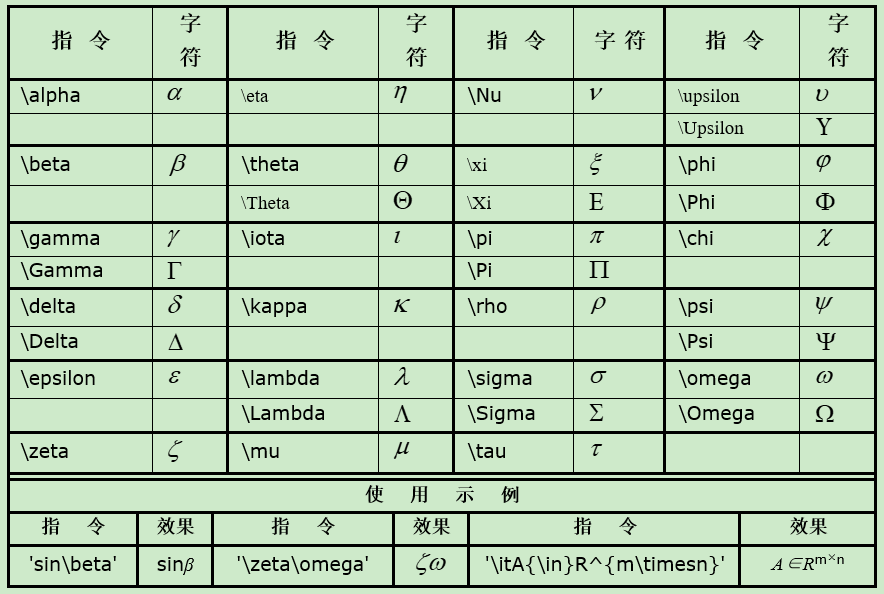

#### `      表`5.2-9  `图形标识用的其他特殊字符（`Tex`字` `符``）`

#### 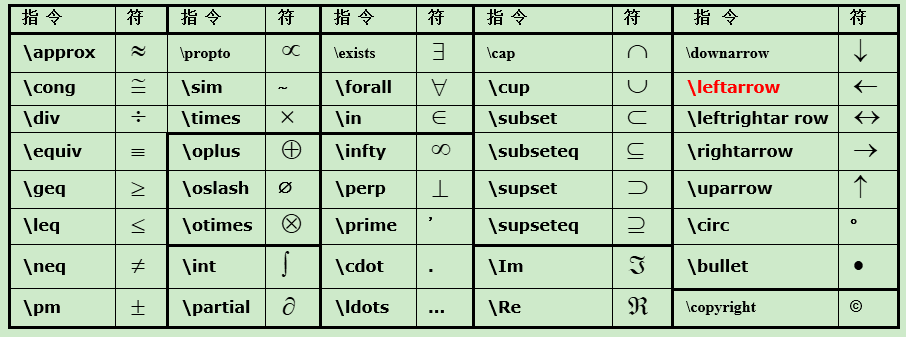   

#### `    表` 5.2-10   `上下标的控制指令` 

#### 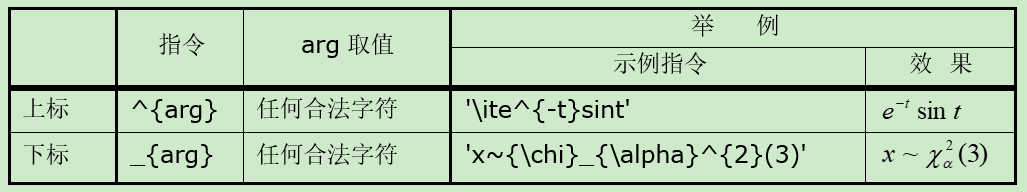

#### `    表` 5.2-11  `字体式样设置规则`     

#### 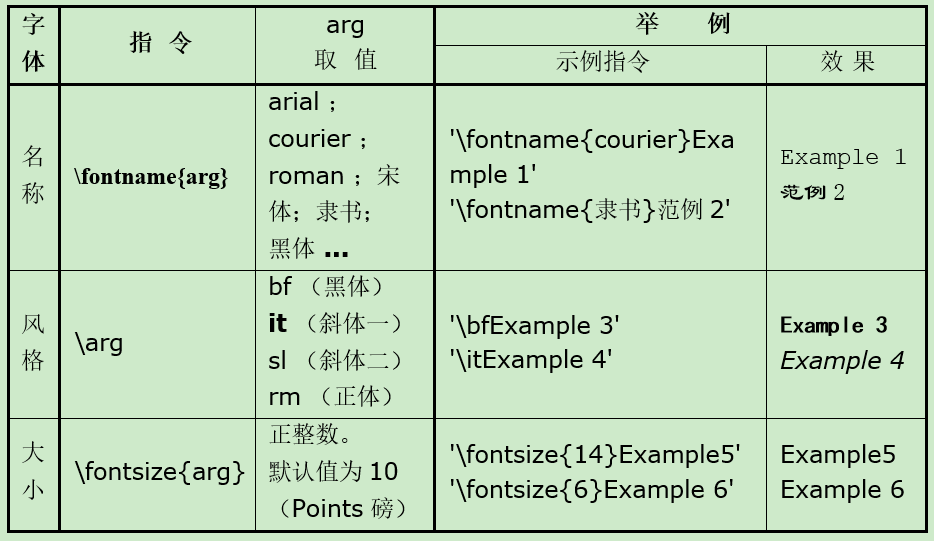

#### `【例`5.2-4`】`

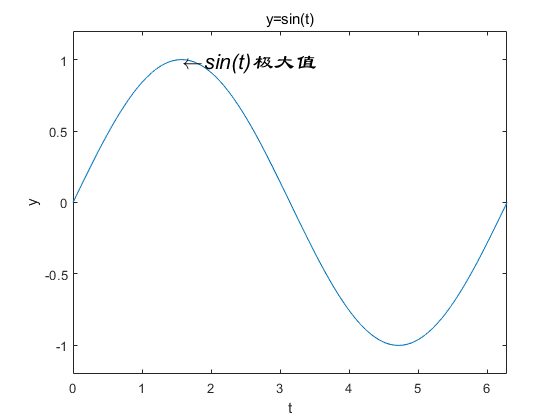

clf;t=0:pi/50:2*pi;
y=sin(t);
plot(t,y)
axis([0,2*pi,-1.2,1.2])
text(pi/2,1,'\fontsize{16}\leftarrow\itsin(t)\fontname{隶书}极大值')                  % <5>
title('y=sin(t)')
xlabel('t')
ylabel('y')  

#### 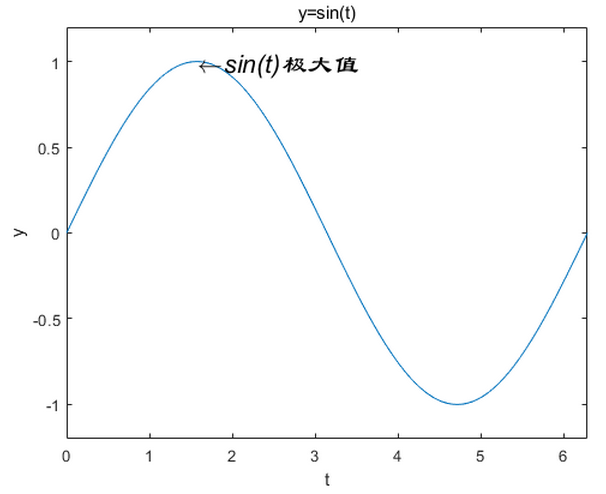

####   `【练习】` 

`    改变`axis`和`plot`的前后顺序观察变化`

`    改变第`<5>`条指令有关参数，观察标识的变化`

#### `【例`5.2-5`】绘制二阶系统阶跃响应曲线`

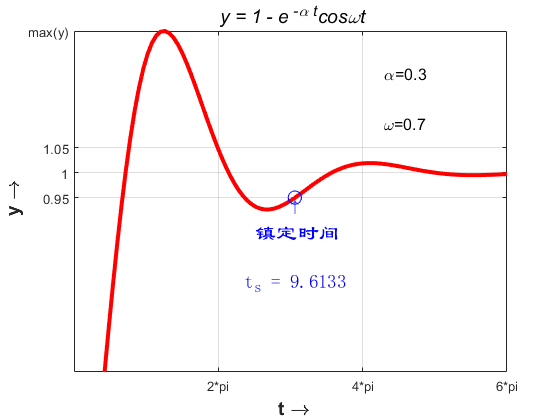

clf;t=6*pi*(0:100)/100;                %数组t(n)，n=0-100
y=1-exp(-0.3*t).*cos(0.7*t);           %数组y(n)，n=0-100
plot(t,y,'r-','LineWidth',3)    
hold on
tt=t(abs(y-1)>0.05);ts=max(tt); 
 %find(X)返回X中所有非零元素的线性索引  
plot(ts,0.95,'bo','MarkerSize',10)               
hold off
axis([-inf,6*pi,0.6,inf])              
set(gca,'Xtick',[2*pi,4*pi,6*pi],'Ytick',[0.95,1,1.05,max(y)]) 
set(gca,'XtickLabel',{'2*pi';'4*pi';'6*pi'})                   
set(gca,'YtickLabel',{'0.95';'1';'1.05';'max(y)'})              
grid on
text(13.5,1.2,'\fontsize{12}{\alpha}=0.3')                     
text(13.5,1.1,'\fontsize{12}{\omega}=0.7')                     
cell_string{1}='\fontsize{12}\uparrow';                            
cell_string{2}='\fontsize{16} \fontname{隶书}镇定时间';
cell_string{3}='\fontsize{6}  ';                         
cell_string{4}=['\fontsize{14}\rmt_{s} = ' num2str(ts)];       
text(ts,0.85,cell_string,'Color','b','HorizontalAlignment','Center')
title('\fontsize{14}\it y = 1 - e^{ -\alpha t}cos{\omegat}')   
xlabel('\fontsize{14} \bft \rightarrow')      
ylabel('\fontsize{14} \bfy \rightarrow')    

####  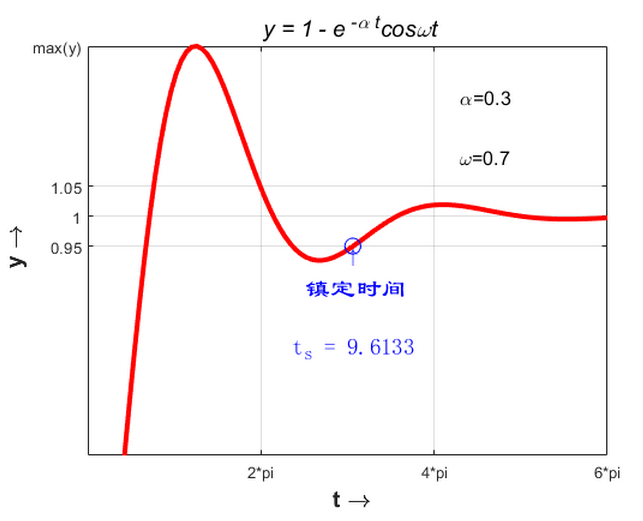

####  5.2.3   `多次叠绘、双纵坐标和多子图`

#### **1、**  `多次叠绘`

`    在同一图形窗里可以绘制几种图形`

`    如不是一次使用`plot, stem, stairs`等绘图指令，就必须使用`hold`指令`

        hold on        `使当前轴及图形保持而不被刷新，准备接受绘制的新曲线。`

        hold off        `使当前轴及图形不再具备不被刷新的性质。`

        hold             `当前图形是否具备刷新性质的双向切换开关。`

#### `【例`5.2-6`】` `利用`hold`绘制离散信号通过零阶保持器后产生的波形。`

t=2*pi*(0:20)/20;
y=cos(t).*exp(-0.4*t);
stem(t,y,'g','Color','k'); 
hold on
stairs(t,y,':r','LineWidth',3)  
hold off   
legend('\fontsize{14}\it stem','\fontsize{14}\it stairs')
box on 

####  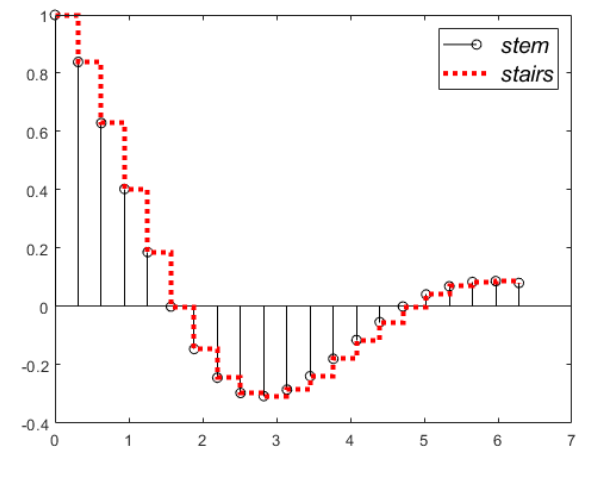

#### `     图``5.2-6`  `离散信号的重构`

#### **2、**     `双纵坐标图`

        yyaxis left          `创建`/`激活具有左纵轴的坐标系`

        yyaxis right        `创建`/`激活具有右纵轴的坐标系`

#### `〖说明〗`

      ` 创建双纵轴坐标系后，可用`plot`、`stairs`、`stem`、`bar`命令画图`

        `双纵坐标是由左、右两个坐标系叠加而成，后者总是叠加在前者之上`

        yyaxis left`（`yyaxis right`）``运行之后才能在左纵轴（右纵轴）上进行操作`

            `如画图、给左（右）纵轴设定区间、分度刻线、分度标识等`

`      默认情况下，左轴系的纵轴、轴名及绘线采用第一默认色`

`      右轴系的纵轴、轴名及绘线采用第二默认色`

#### `【例`5.2-8`】采用双纵坐标轴绘制“`1978~2016`全国`GDP`和城镇居民人均可支配收入”的统计曲线。`

#### `（``1``）统计数据的输入`

clear                           % 
x=1978:2016;
yL=[3645,4062,4545,4892,5323,5962,7208,9016,10275,12058,15042, 16992,18667,...
       21781,26923,35333,48197,60973,71176,78973,84402, 89677,99214,109655,120332,...
       135822,159878,184937,216314, 265810,314045,340903,410202,472882,...
       519322,568845,636463,676708,744127];         %
yR=[343,387,477,491,526,564,651,739,899,1002,1181,1373,1510,1700, 2026,2577,...
        3496,4283,4838,5160,5425,5854,6280,6860,7702,8472, 9421,10493,11759,...
       13786,15781,17175,19109,21810,24565,26955,28844,31195,33616];     %   

#### `（``2``）默认设置下的双纵坐标图线`

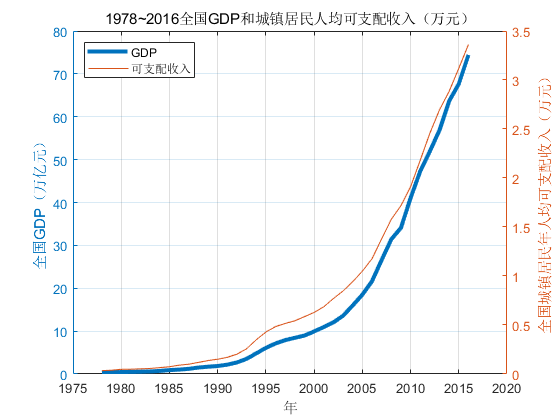

close all                               %       <12>
figure                                  % 
yyaxis left                         %建立左纵轴坐标系
yyaxis left                         % <14>
plot(x,yL*1e-4,'LineWidth',3)       %       <15>
ylim([0,80])                        % 左纵轴区间 <16>
ylabel('全国GDP（万亿元）')            % 
grid on                             %        <22>
yyaxis right                        % 建立右纵轴坐标系  <18>
plot(x,yR*1e-4)                     %   <19>
ylim([0,3.5])                           % <20>
ylabel('全国城镇居民年人均可支配收入（万元）')% 
xlabel('年')
title('1978~2016全国GDP和城镇居民人均可支配收入（万元）') %默认色
legend('GDP','可支配收入','Location','NorthWest')   %<26> 

####  `图`5.2-9 `默认设置下的双色纵轴图`

#### `（``3``）用户自定义图形色和纵轴、轴名、双纵坐标图线`

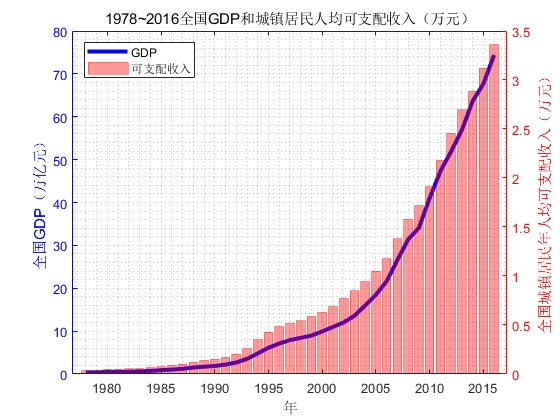

figure                                  %    <27>
Ax=gca;                             % 获取轴系句柄
yyaxis left                         %       <29>
Lc='b';                             % 左系自定义用色
plot(x,yL*1e-4,'Color',Lc,'LineWidth',3);   %   <31>
Ax.YColor=Lc;                       % 左系用色一样      <32>
ylabel('全国GDP（万亿元）','Color',Lc);        %       <33>
ylim([0,80]);                                  %       <34>
yyaxis right                                %          <35>
Rc='r';                                       % 
bar(x,yR*1e-4,'FaceColor',Rc,'FaceAlpha',0.4,'EdgeColor',Rc,...
    'EdgeAlpha',0.4)                %直方图  <38>
Ax.YColor=Rc;                       %右纵轴图均取Rc色  <39>
ylabel('全国城镇居民年人均可支配收入（万元）','Color',Rc) % <40> %
ylim([0,3.5]);                          %               <42>
xlabel('年')                         % 
grid('minor')                           %               <44>
title('1978~2016全国GDP和城镇居民人均可支配收入（万元）')    % 
legend('GDP','可支配收入','Location','NorthWest')    

 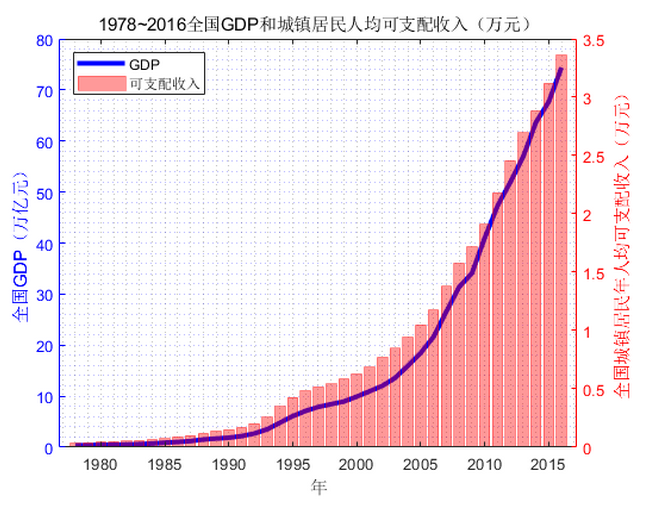

                图5.2-9 自定义设置下的双色纵轴图

#### 3、  多坐标系的铺放

    MATLAB允许在一个图形窗中画多幅独立的子图

    subplot(m,n,k)           使 幅子图中的第 幅成为当前图

    subplot('position',[left bottom width height])   

`    在指定位置上开辟子图，并成为当前图`

#### `〖说明〗`

      Subplot`产生的坐标轴系相互独立`

      position`属性：图形窗口的位置与大小`

`      属性值：`[left, bottom, width, height]

            left, bottom`是窗口左下角横纵坐标`

            `采用归一化单位，即宽高取值范围都是`[0,1]`，左下角坐标为`(0,0)

#### `【例`5.2-8`】演示`subplot`指令对图形窗的分割（图`5.2-8`）。`

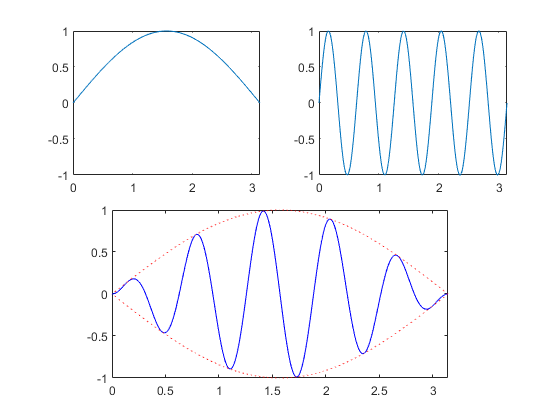

clf;t=(pi*(0:1000)/1000)';
y1=sin(t);y2=sin(10*t);
y12=sin(t).*sin(10*t);
subplot(2,2,1),plot(t,y1);
axis([0,pi,-1,1])
subplot(2,2,2),plot(t,y2);
axis([0,pi,-1,1])
subplot('position',[0.2,0.1,0.6,0.40])   
plot(t,y12,'b-',t,[y1,-y1],'r:')      % 画包络线
axis([0,pi,-1,1])  

#### 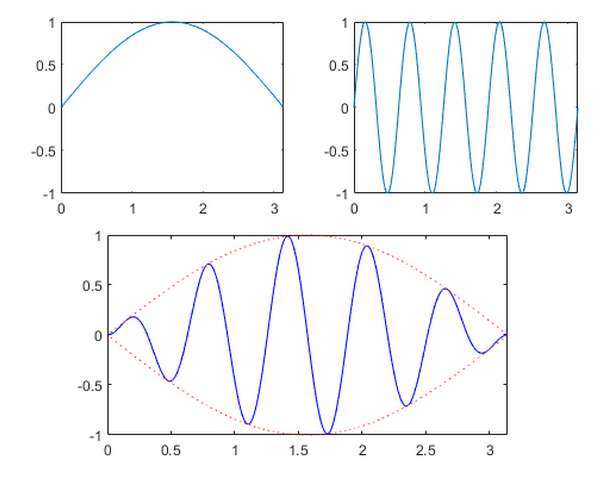 

#### `        图` `5.2-8`  `多子图的布置`

#### 5.2.4   `获取二维图形数据的指令`**ginput**

    [x,y]=ginput(n)   `用鼠标从二维图形上获取`n`个点的数据坐标`(x,y) 

    [x,y]=ginput          `用鼠标从二维图形上获取任意个点的坐标`(x,y)`数据`

`    回车键结束输入`

    [x,y,button]=ginput(n)     `按鼠标左中右键，`button`分别返回`1,2,3

`    输入键盘键返回`ASCII`码`

#### `〖说明〗`  `指令只适用于二维图形`

#### `【例`5.2-9`】采用图解法求``的解。`

#### `（`1`）绘制`  `的曲线`

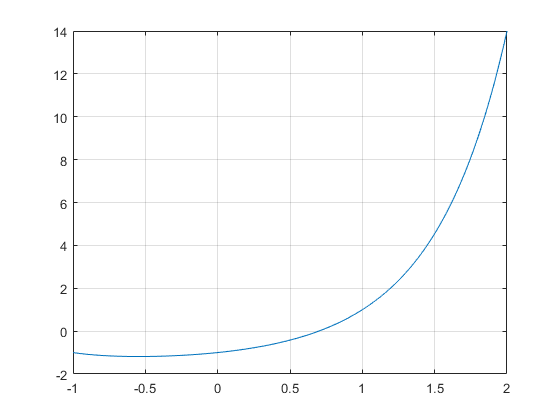

clf
x=-1:0.01:2;
y=(x+2).^x-2;
plot(x,y)
grid on  

#### `（`2`）放大图形取点`

% [x,y] = ginput(1) %exp;    %放大局部图形有利于获取点的坐标。

#### `（`3`）显示结果`

format long
x,y     

x =   -1.000000000000000  -0.990000000000000  -0.980000000000000  -0.970000000000000  -0.960000000000000  -0.950000000000000  -0.940000000000000  -0.930000000000000  -0.920000000000000  -0.910000000000000  -0.900000000000000  -0.890000000000000  -0.880000000000000  -0.870000000000000  -0.860000000000000  -0.850000000000000  -0.840000000000000  -0.830000000000000  -0.820000000000000  -0.810000000000000  -0.800000000000000  -0.790000000000000  -0.780000000000000  -0.770000000000000  -0.760000000000000  -0.750000000000000  -0.740000000000000  -0.730000000000000  -0.720000000000000  -0.710000000000000  -0.700000000000000  -0.690000000000000  -0.680000000000000  -0.670000000000000  -0.660000000000000  -0.650000000000000  -0.640000000000000  -0.630000000000000  -0.620000000000000  -0.610000000000000  -0.600000000000000  -0.590000000000000  -0.580000000000000  -0.570000000000000  -0.560000000000000  -0.550000000000000  -0.540000000000000  -0.530000000000000  -0.520000000000000  -0.51000000000

y =   -1.000000000000000  -1.009802467070148  -1.019219479426384  -1.028264895768208  -1.036951865594812  -1.045292870257367  -1.053299761232049  -1.060983795825245  -1.068355670504495  -1.075425552032452  -1.082203106566467  -1.088697526872903  -1.094917557793232  -1.100871520087732  -1.106567332772629  -1.112012534057220  -1.117214300979142  -1.122179467828286  -1.126914543442794  -1.131425727454187  -1.135718925552793  -1.139799763839225  -1.143673602322761  -1.147345547622922  -1.150820464926385  -1.154102989247549  -1.157197536037563  -1.160108311183373  -1.162839320435378  -1.165394378299544  -1.167777116427286  -1.169990991534093  -1.172039292875726  -1.173925149308821  -1.175651535960885  -1.177221280532986  -1.178637069256843  -1.179901452526578  -1.181016850224044  -1.181985556755365  -1.182809745815198  -1.183491474894123  -1.184032689543568  -1.184435227411753  -1.184700822063280  -1.184831106594150  -1.184827617053310  -1.184691795681055  -1.184424993974022  -1.18402847558

#### `x =`

####      `0.69828692903537`

#### `y =`

####      `-5.884401711382421e-010`  

#### 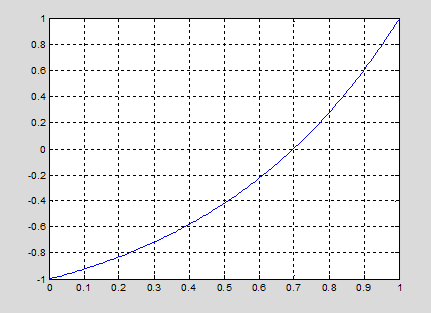    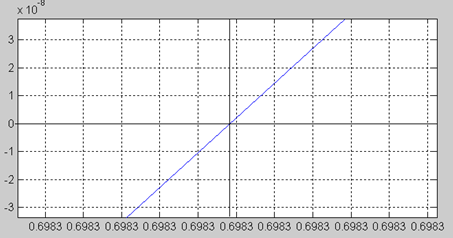                      

#### `图``5.2-9`   `经多次区间段试探后画出的图形`                `图``5.2-9``  局部放大图`

#### 5.3   `三维曲线和曲面`

#### 5.3.1   `三维线图指令`**plot3**

    plot3(X,Y,Z,'s')     `用`s `指定的点形、线型和色彩绘制曲线`

    plot3(X1,Y1,Z1,'s1',X2,Y2,Z2,'s2', ... )        

`    用`s1, s2 …`指定的点形线型色彩绘制多类曲线`

#### `〖说明〗`

       plot3`主要表现单参数三维曲线，用法与`plot`类似`

       X,Y,Z`是同维列数组时，绘制以`X,Y,Z`元素为`x,y,z`坐标的三维曲线`

           X,Y,Z`是同维矩阵时，以`X,Y,Z`对应``列``元素为`x,y,z`坐标`

`     分别绘制三维曲线，曲线条数等于矩阵列数`

       x,y,z`常采用参变量函数表达形式：`x=f1(t)`，`y=f2(t)`，`z=f3(t)

    `绘线四元组之间没有约束关系`

#### `【例`5.3-1`】三维曲线绘图。本例演示：`

#### `三维曲线的参数方程；``线型、点形和图例。``（图`5.3-1`）`

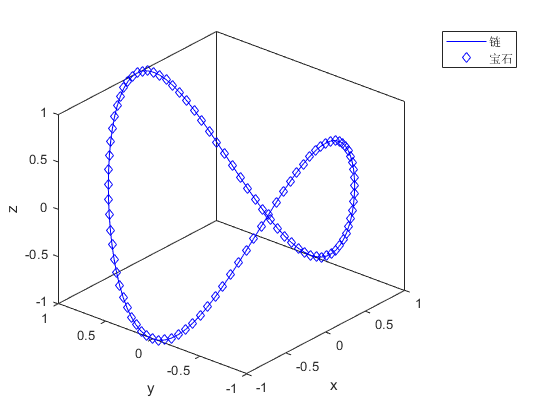

t=(0:0.02:2)*pi;
x=sin(t);y=cos(t);z=cos(2*t);   
plot3(x,y,z,'b-',x,y,z,'bd')    % plot用法
view([-50,30]),box on
xlabel('x'),ylabel('y'),zlabel('z')
legend('链','宝石')  

#### 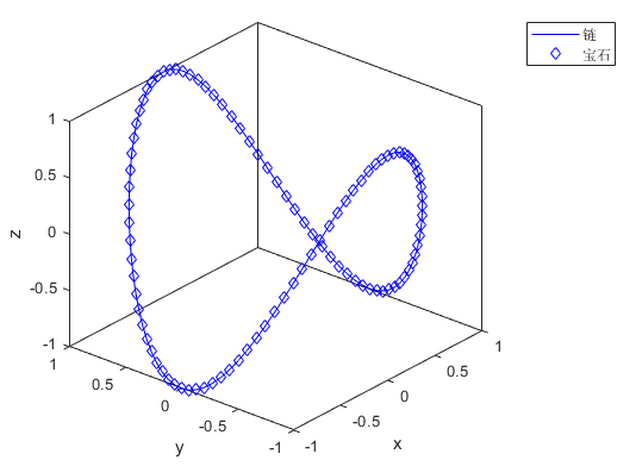 

#### `        图`5.3-1  `宝石项链`